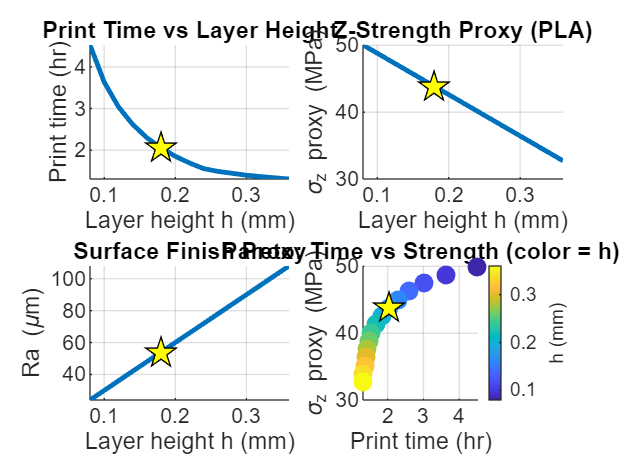

%% Vreman 3D Lab — Layer Height Optimizer (FDM, version-safe Live Script)
% Tradeoff: print time vs Z-strength (proxy) vs surface finish (Ra)
% Compatibility notes: no strings, no tiledlayout, no xline.

%% 1) Printer & material (edit to your rig)
printer_name = 'Vreman 3D Lab — Core FDM';
nozzle_d     = 0.4;     % mm (brass 0.4 default)
line_width   = 0.48;    % mm (≈1.2× nozzle)
Qmax         = 14;      % mm^3/s (extruder max volumetric flow)
v_perim_set  = 50;      % mm/s
v_infill_set = 120;     % mm/s

material_name   = 'PLA';
sigma_bulk_MPa  = 55;   % XY tensile bulk (datasheet ballpark)

% Strength drop coefficient vs h/nozzle_d by material
a_coeff = 0.45; % PLA default; try 0.35 PETG, 0.55 ABS if desired

%% 2) Part geometry (edit per job)
part_name  = 'Bracket (estimate)';
H          = 60;      % mm build Z height
Axy        = 1800;    % mm^2 avg cross-section area per layer
Pxy        = 200;     % mm   avg outer perimeter length
perims     = 3;       % wall count
infill_pct = 0.30;    % 0..1
top_layers = 6;       % solid
bot_layers = 6;       % solid

%% 3) Candidate layer heights
h_vals = (0.08:0.02:0.36)';   % mm

%% 4) Layer counts & speeds
N_layers = @(h) ceil(H./h);
solid_layers = @(h) min(top_layers+bot_layers, N_layers(h));
v_eff = @(vset,h) min(vset, Qmax./(line_width.*h)); % mm/s

%% 5) Per-layer times
L_perim   = @(h) Pxy*perims;            % mm
A_solid   = @(h) Axy;
A_infill  = @(h) Axy.*infill_pct;
L_infill  = @(A) A./line_width;         % mm

t_layer_solid = @(h) (L_perim(h)./v_eff(v_perim_set,h)) ...
                   + (L_infill(A_solid(h))./v_eff(v_infill_set,h));
t_layer_grid  = @(h) (L_perim(h)./v_eff(v_perim_set,h)) ...
                   + (L_infill(A_infill(h))./v_eff(v_infill_set,h));

t_print = zeros(numel(h_vals),1);
for i=1:numel(h_vals)
    h = h_vals(i);
    N  = N_layers(h);
    Ns = min(solid_layers(h), N);
    Nm = max(N - Ns, 0);
    t_print(i) = Ns*t_layer_solid(h) + Nm*t_layer_grid(h); % seconds
end
t_print_hr = t_print/3600;

%% 6) Surface finish proxy
Ra_um = 1000*(0.30*h_vals);   % μm (Ra ≈ 0.3*h rule of thumb)

%% 7) Z-strength proxy
sigma_rel   = max(min(1 - a_coeff*(h_vals./nozzle_d), 1.0), 0.30);
sigma_z_MPa = sigma_bulk_MPa .* sigma_rel;

%% 8) Simple composite score (lower = better)
t_n  = (t_print_hr - min(t_print_hr)) ./ max(eps, (max(t_print_hr)-min(t_print_hr)));
Ra_n = (Ra_um      - min(Ra_um))      ./ max(eps, (max(Ra_um)-min(Ra_um)));
s_n  = 1 - ( (sigma_z_MPa - min(sigma_z_MPa)) ./ max(eps, (max(sigma_z_MPa)-min(sigma_z_MPa))) );

w_time = 0.5; w_finish = 0.2; w_strength = 0.3;
score = w_time*t_n + w_finish*Ra_n + w_strength*s_n;
[bestScore, idxBest] = min(score); 

best_h   = h_vals(idxBest);
best_t   = t_print_hr(idxBest);
best_Ra  = Ra_um(idxBest);
best_sig = sigma_z_MPa(idxBest);

%% 9) Plots (version-safe: subplot only)
figure('Name','Vreman 3D Lab | Layer Height Trade-offs','Color','w');

subplot(2,2,1); grid on; hold on
plot(h_vals, t_print_hr, 'LineWidth',1.8);
plot(best_h, best_t, 'kp', 'MarkerSize',12, 'MarkerFaceColor','y');
xlabel('Layer height h (mm)'); ylabel('Print time (hr)');
title('Print Time vs Layer Height');

subplot(2,2,2); grid on; hold on
plot(h_vals, sigma_z_MPa, 'LineWidth',1.8);
plot(best_h, best_sig, 'kp', 'MarkerSize',12, 'MarkerFaceColor','y');
xlabel('Layer height h (mm)'); ylabel('\sigma_z proxy (MPa)');
title(['Z-Strength Proxy (', material_name, ')']);

subplot(2,2,3); grid on; hold on
plot(h_vals, Ra_um, 'LineWidth',1.8);
plot(best_h, best_Ra, 'kp', 'MarkerSize',12, 'MarkerFaceColor','y');
xlabel('Layer height h (mm)'); ylabel('Ra (\mum)');
title('Surface Finish Proxy');

subplot(2,2,4); grid on; hold on
scatter(t_print_hr, sigma_z_MPa, 50, h_vals, 'filled');
plot(best_t, best_sig, 'kp', 'MarkerSize',12, 'MarkerFaceColor','y');
cb=colorbar; ylabel(cb,'h (mm)');
xlabel('Print time (hr)'); ylabel('\sigma_z proxy (MPa)');
title('Pareto: Time vs Strength (color = h)');


%% 10) Summary (Command Window)
fprintf('\n=== Vreman 3D Lab — Suggested Layer Height ===\n');


=== Vreman 3D Lab — Suggested Layer Height ===


fprintf('Part: %s | Material: %s | Nozzle: %.2f mm\n', part_name, material_name, nozzle_d);

Part: Bracket (estimate) | Material: PLA | Nozzle: 0.40 mm


fprintf('Best h = %.2f mm | Time ≈ %.2f hr | Ra ≈ %.0f μm | σ_z ≈ %.1f MPa\n\n', ...
        best_h, best_t, best_Ra, best_sig);

Best h = 0.18 mm | Time ≈ 2.06 hr | Ra ≈ 54 μm | σ_z ≈ 43.9 MPa

